# Optimization Stochastic Gradient Descent

It's a method used to update the parameters of your model/hypothesis during the training phase. The trainning loop  has the following steps:

Loop:

- Sample a batch of data

- Forward propagate to calculate the loss and layer outputs

- Backpropagate to calculate the gradients of each layer

- **Update the parameters (Use gradient descent) **$\theta_{new}=\theta_{old}-\alpha.\frac{\partial }{\partial \theta}L(\theta)$

Observe again on the step 4 (Gradient descent operation), that there is a derivative term, that need to be calculated, which is the derivative of your loss function with respect to each parameter. On this tutorial we will use calculus to discover them but on the future we will talk about Backpropagation that help you calculate the gradient of your model with respect to it's parameters

## Some points on Optimization

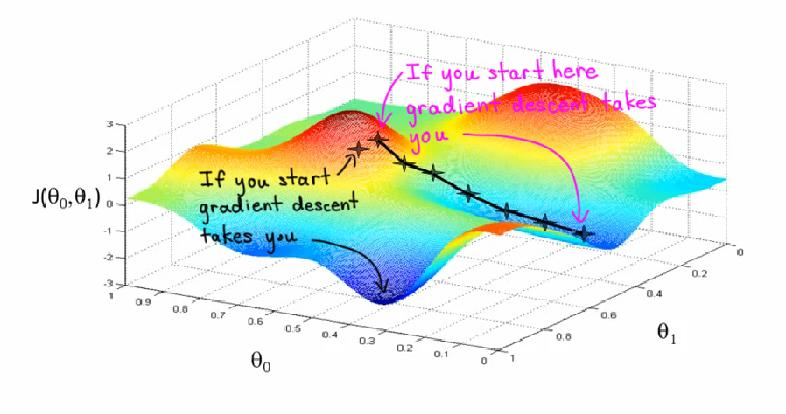

There is no garantee that the gradient descent method will found the global minima of your function, but still is a very good method for optimization.

For more information about optimization:

- [Notes on optimization part 1](http://cs231n.github.io/optimization-1/)

- [Notes on optimization part 2](http://cs231n.github.io/optimization-2/)

## Learning Rate

You must pay attention on the choice of the learning rate, if you use a small $\alpha$ the optimization will take to long, or if you choose a big $\alpha
$ you can overshoot.

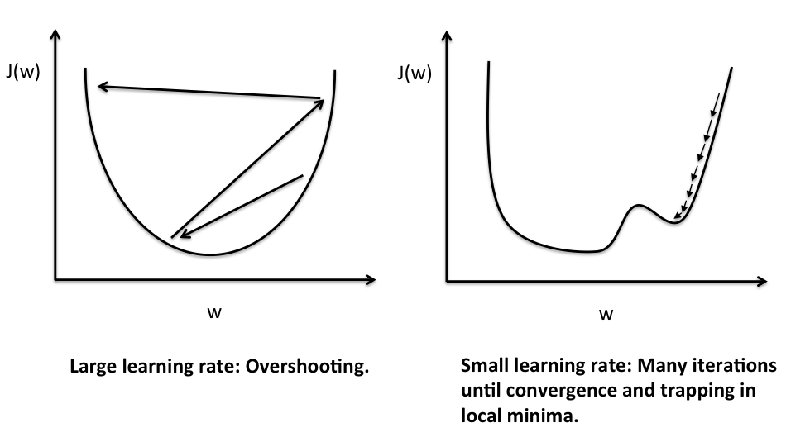

## Simple example

Consider the following function $f(x)=x^4-3.x^3+2$, if we want to use calculus to knot it's local minimas, we need to calculate it's derivatives $\frac{\partial}{\partial x}f(x)=4.x^3-9.x^2$, then solve the result to check it's (minima, maxima or sadle) points.

syms x;
% Define function f(x)
f_x = x^4-3*x^3+2;
pretty(f_x);

 4      3
x  - 3 x  + 2




% Calculate derivative d(f(x))/dx
deriv_f_x = diff(f_x,x);
pretty(deriv_f_x);

   3      2
4 x  - 9 x




% Look for critical points (Solve derivative equal to zero)
crit_pts = solve(deriv_f_x);
fprintf('Local minimum found with calculus at %.2d \n',double(max(crit_pts)));

Local minimum found with calculus at 2.25e+00 


Plotting original function with it's critical points

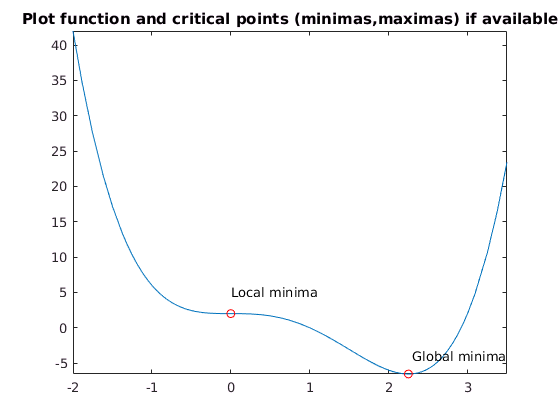

% Plot function
fplot(matlabFunction(f_x),[-2 3.5]);
title('Plot function and critical points (minimas,maximas) if available');
hold on
plot(double(crit_pts), double(subs(f_x,crit_pts)),'ro');
text(0,5,'Local minima');
text(2.3,-4,'Global minima');
hold off

## Using gradient descent

% Choose a starting point
x_new = 0.5;

% Choose an alpha
alpha = 0.01;

% Get the derivative of the function
f_derivative = matlabFunction(deriv_f_x);

% Gradient descent loop
for idxEpochs=1:1000
    delta = f_derivative(x_new);
    x_new = x_new - alpha * f_derivative(x_new);    
end

correct_result = 9/4;
error = abs(x_new - correct_result);
fprintf('Local minimum found at %.2d and should be %.2d error=%.2d\n',x_new,correct_result,error);

Local minimum found at 2.25e+00 and should be 2.25e+00 error=4.44e-16
